# **Q3 Self-Organizing Map (SOM)**

## **Q3a: 1D SOM for Sinc Function**

clc; clear;
% Generate training data
x = linspace(-pi, pi, 400);
trainX = [x; sinc(x)]; % 2x400 matrix

% SOM parameters
num_neurons = 40;       % Number of neurons in the 1D lattice
epochs = 500;         % Training iteration
eta0 = 1.0;             % Initial learning rate
sigma0 = num_neurons/2; % Initial neighborhood width (half the grid length)

% weight initialization
rng(2025); % seed for reproducibility
weights = rand(num_neurons, 2)*2 - 1; % Random weights in [-1, 1]

% training process
for epoch = 1:epochs
    % Select samples randomly
    sample_idx = randi(size(trainX,2));
    sample = trainX(:, sample_idx);
    
    % Competition (Find a winner)
    distances = sum((weights - sample').^2, 2); % Squared Euclidean distance
    [~, winner] = min(distances);
    
    % Exponential decay
    lr = eta0 * exp(- epoch/epochs); % learning rate decay
    sigma = sigma0 * exp(-epoch/(epochs/log(sigma0))); % neighborhood width decay
    
    % Adaptation (Weight Update)
    neuron_indices = 1:num_neurons;
    distances_to_winner = abs(neuron_indices - winner);
    neighborhood = exp(-distances_to_winner.^2 / (2*sigma^2));
    delta = lr * neighborhood' .* (sample' - weights);
    weights = weights + delta;
end

% Visualization
figure;
scatter(trainX(1,:), trainX(2,:), 10, '+r'); hold on;
plot(weights(:,1), weights(:,2), 'b-o', 'LineWidth', 1.5);
legend('Sinc','SOM');
title(sprintf('1D SOM on Sinc Function (epoch=%d)', epochs));
xlabel('x'); ylabel('sinc(x)');
axis equal;

## Q3b: 2D SOM for Circle Data

% Generate training data
rng(2025);
X = randn(800,2);
s2 = sum(X.^2, 2);
% trainX = X .* (gammainc(s2/2, 1).^(1/2) ./ sqrt(s2));
% trainX = trainX'; % 2x800 matrix
trainX = (X.*repmat(1*(gammainc(s2/2,1).^(1/2))./sqrt(s2),1,2))';

% SOM parameters
grid_size = [8 8];            % 2D grid size (8x8 neurons)
epochs = 300;               % Training iterations
eta0 = 0.1;                   % Initial learning rate
sigma0 = sqrt(grid_size(1)^2+grid_size(2)^2)/2;  % Initial neighborhood width (half of grid diagonal)

% Initialize weights
weights = rand(grid_size(1), grid_size(2), 2)*2 - 1;  % Random weights in [-1, 1]

% Training process
for epoch = 1:epochs
    % Randomly select a sample
    sample_idx = randi(size(trainX,2));
    sample = trainX(:, sample_idx);
    
    % Find winning neuron (minimum Euclidean distance)
    distances = vecnorm(reshape(weights, [], 2) - sample', 2, 2);
    [~, winner_idx] = min(distances);
    [i_win, j_win] = ind2sub(grid_size, winner_idx);
    
    % Calculate learning rate and neighborhood width
    lr = eta0 * exp(-epoch/epochs);                % Learning rate decay
    sigma = sigma0 * exp(-epoch/(epochs/log(sigma0)));  % Neighborhood width decay
    
    % Update weights
    for i = 1:grid_size(1)
        for j = 1:grid_size(2)
            distance = sqrt((i - i_win)^2 + (j - j_win)^2);  % Grid distance to winner
            neighborhood = exp(-distance^2/(2*sigma^2));     % Gaussian neighborhood
            weights(i,j,:) = squeeze(weights(i,j,:)) + lr*neighborhood*(sample - squeeze(weights(i,j,:)));
        end
    end
end

% Visualization
figure;
scatter(trainX(1,:), trainX(2,:), 10, 'r+'); hold on;  % Plot training data

% Draw neuron connections
for i = 1:grid_size(1)
    for j = 1:grid_size(2)
        % Horizontal connections
        if j < grid_size(2)
            plot([weights(i,j,1), weights(i,j+1,1)],...
                 [weights(i,j,2), weights(i,j+1,2)], 'k-');
        end
        % Vertical connections
        if i < grid_size(1)
            plot([weights(i,j,1), weights(i+1,j,1)],...
                 [weights(i,j,2), weights(i+1,j,2)], 'k-');
        end
    end
end

scatter(reshape(weights(:,:,1),[],1), reshape(weights(:,:,2),[],1), 50, 'b', 'filled');  % Plot neuron weights
title(sprintf('2D SOM on Circle Data (epoch=%d)',epochs));
axis equal;

## Q3c: SOM for Digit Classification


clc;clear;

%% Data Loading & Preprocessing
% Load dataset
load('./Digits.mat');

% Determine omitted classes based on student ID (last digit=9)
last_digit = 9;
omitted_class1 = mod(last_digit, 5);       % Class 4 (since 9%5=4)
omitted_class2 = mod(last_digit+1, 5);     % Class 0 (since (9+1)%5=0)

% Filter training data (exclude classes 0 and 4)
train_mask = ~ismember(train_classlabel, [omitted_class1, omitted_class2]);
Train_Data = train_data(:, train_mask);    % [784xN] matrix
Train_Label = train_classlabel(train_mask);% [1xN] vector

%% SOM Training
% Parameters
grid_size = [10 10];       % SOM grid dimensions
input_dim = 784;           % Input dimension (28x28 images)
epochs = 10000;            % Training iterations
eta0 = 0.1;                % Initial learning rate
sigma0 = 5.0;              % Initial neighborhood radius
rng(2025);
weights = rand(grid_size(1), grid_size(2), input_dim); % Random initialization

%% Training Loop
for epoch = 1:epochs
    % Randomly select a sample
    sample_idx = randi(size(Train_Data,2));
    sample = Train_Data(:, sample_idx);
    
    % Find Best Matching Unit (BMU)
    distances = vecnorm(reshape(weights, [], input_dim) - sample', 2, 2);
    [~, winner_idx] = min(distances);
    [i_win, j_win] = ind2sub(grid_size, winner_idx);
    
    % Update learning rate and neighborhood radius
    lr = eta0 * exp(-epoch/epochs);                % Exponential decay
    sigma = sigma0 * exp(-epoch/(epochs/log(sigma0))); 
    
    % Update weights for all neurons
    for i = 1:grid_size(1)
        for j = 1:grid_size(2)
            distance = sqrt((i - i_win)^2 + (j - j_win)^2);
            neighborhood = exp(-distance^2/(2*sigma^2));
            weights(i,j,:) = squeeze(weights(i,j,:)) + lr*neighborhood*(sample - squeeze(weights(i,j,:)));
        end
    end
end

%% Label Mapping
% Assign BMUs for all training samples
weights_flat = reshape(weights, [], input_dim);        % [100x784]
distances_all = pdist2(Train_Data', weights_flat);     % [N_trainx100]

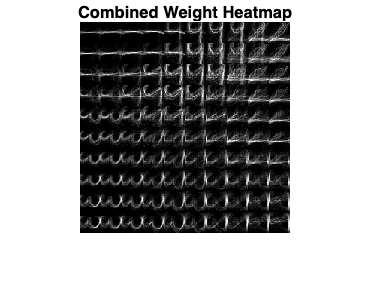

[~, assignments] = min(distances_all, [], 2);          % BMU indices

% Generate label map using majority voting
label_map = zeros (grid_size);
for neuron_idx = 1:prod(grid_size)
    mask = (assignments == neuron_idx);
    if sum(mask) > 0
        [i,j] = ind2sub(grid_size, neuron_idx);
        label_map(i,j) = mode(Train_Label(mask));      % Majority class
    end
end

%% Weight Heatmap
% Combine all neuron weights into a single image
all_imgs = zeros(28*grid_size(1), 28*grid_size(2));
for i = 1:grid_size(1)
    for j = 1:grid_size(2)
        img = reshape(weights(i,j,:), 28, 28);
        img = (img - min(img(:))) / (max(img(:)) - min(img(:)) + eps); % Normalize
        all_imgs((i-1)*28+1:i*28, (j-1)*28+1:j*28) = img;
    end
end
figure; imshow(all_imgs); title('Combined Weight Heatmap');


fprintf('Unique activated neurons: %d/100\n', numel(unique(assignments)));

Unique activated neurons: 97/100


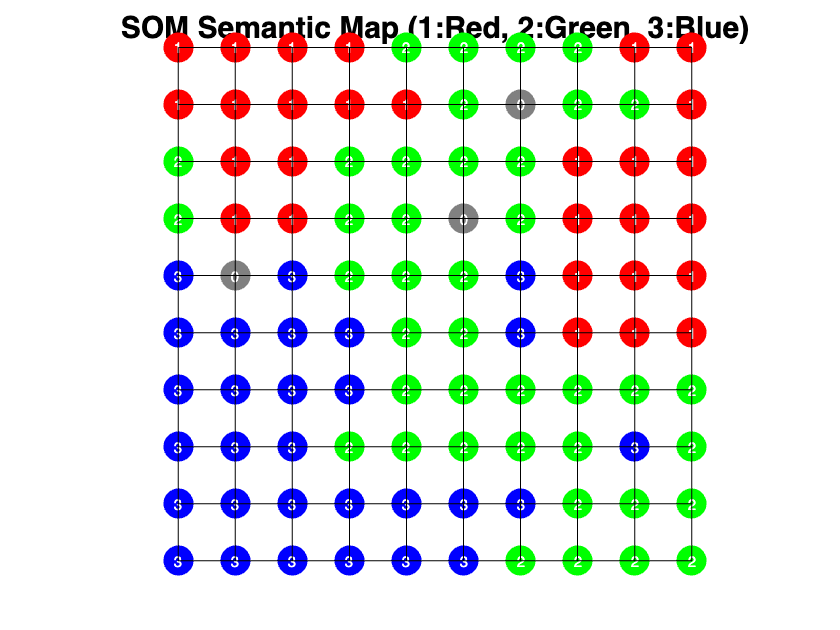


%% Semantic Map
figure; axis equal; hold on;
color_map = [1 0 0; 0 1 0; 0 0 1; 0.5 0.5 0.5]; % RGB for classes 1/2/3/gray

% Plot neurons with class labels
for i = 1:grid_size(1)
    for j = 1:grid_size(2)
        x = j; y = grid_size(1) - i + 1;
        class_id = label_map(i,j);
        if ~ismember(class_id, [1,2,3]), class_id = 4; end % Unlabeled neurons
        scatter(x, y, 400, 'filled', 'MarkerFaceColor', color_map(class_id,:));
        text(x, y, num2str(label_map(i,j)), 'HorizontalAlignment', 'center', 'Color', 'w');
    end
end

% Draw grid connections
for i = 1:grid_size(1)
    for j = 1:grid_size(2)
        x1 = j; y1 = grid_size(1) - i + 1;
        if j < grid_size(2), line([x1, x1+1], [y1, y1], 'Color', 'k'); end % Horizontal
        if i < grid_size(1), line([x1, x1], [y1, y1-1], 'Color', 'k'); end % Vertical
    end
end
title('SOM Semantic Map (1:Red, 2:Green, 3:Blue)','FontSize',20); axis off;

## Testing & Evaluation

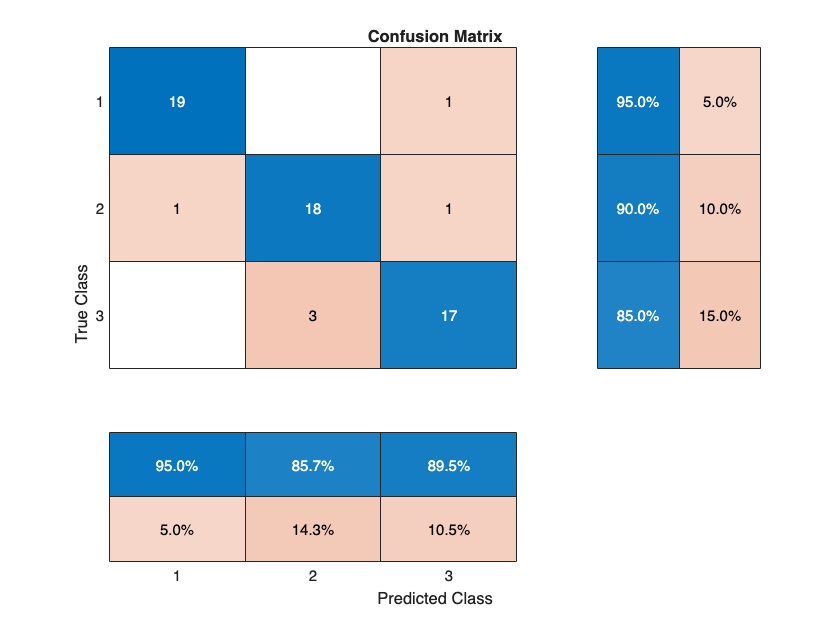


% Prediction with Fallback

% Preprocess test data (exclude classes 0/4)
valid_test_mask = ismember(test_classlabel, [1,2,3]);
Test_Data = test_data(:, valid_test_mask);
Test_Labels = test_classlabel(valid_test_mask);

% Predict labels with BMU skipping unlabeled neurons
test_pred = zeros(1, size(Test_Data,2));
for k = 1:size(Test_Data,2)
    sample = Test_Data(:, k);
    distances = vecnorm(weights_flat - sample', 2, 2);
    [~, sorted_idx] = sort(distances);
    
    % Find the first valid BMU
    attempt = 1;
    while attempt <= length(sorted_idx)
        winner_idx = sorted_idx(attempt);
        [i_win, j_win] = ind2sub(grid_size, winner_idx);
        if label_map(i_win, j_win) ~= 0, break; end
        attempt = attempt + 1;
    end
    
    % Fallback to majority class if all BMUs are invalid
    if label_map(i_win, j_win) == 0
        test_pred(k) = mode(Train_Label);
    else
        test_pred(k) = label_map(i_win, j_win);
    end
end

% Confusion Matrix & Accuracy
C = confusionmat(Test_Labels, uint8(test_pred), 'Order', [1,2,3]);
figure; confusionchart(C, {'1','2','3'}, ...
    'Title', 'Confusion Matrix', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

accuracy = sum(diag(C)) / sum(C(:));
fprintf('Test Accuracy: %.2f%%\n', accuracy*100);

Test Accuracy: 90.00%
